# LTI Parameter Surfaces

## for

# `longitudinal Vehicle Motion Control from gain scheduled LTI systems modeled on more complex dynamics.`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`8/22/23`

` Ohio State University`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# Loading in the Data

clc; clear; close all;
load('longitudinalModelData80923.mat')
LMD = longitudinalModelData80823

LMD = 107×11 table
     Vs     Tm_Tb       K          T          rmse       time     avg_acc       dX        Ve      Tm     Tb
    ____    _____    ________    ______    __________    ____    _________    ______    ______    ___    __

       0       0      0.52277    198.47      0.013211      0             0         0         0      0    0 
    0.01      55      0.53809    111.13      0.010918    600      0.049325     14695    29.605     55    0 
    0.01      80      0.48331    85.937     0.0091168    600      0.064442     20125    38.675     80    0 
    0.01     105      0.43781    71.785     0.0078491    600      

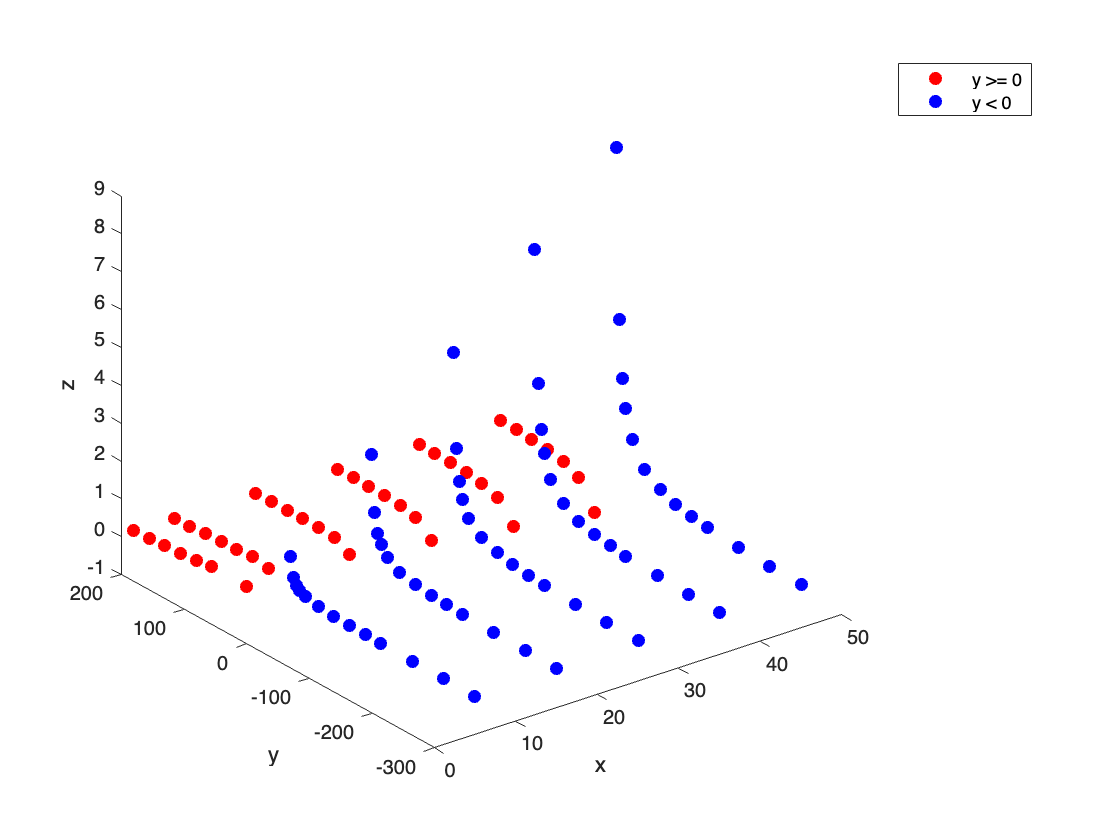

n = length(LMD.Vs);

x = LMD.Vs;
y = LMD.Tm_Tb;
k = LMD.K;
t = LMD.T;
rmse = LMD.rmse;

figure;

% Points where y >= 0
idx_positive = y >= 0;
plot3(x(idx_positive), y(idx_positive), k(idx_positive), 'ro', 'MarkerFaceColor', 'r');

hold on;

% Points where y < 0
idx_negative = y < 0;
plot3(x(idx_negative), y(idx_negative), k(idx_negative), 'bo', 'MarkerFaceColor', 'b');

xlabel('x');
ylabel('y');
zlabel('z');

legend('y >= 0', 'y < 0');

hold off;

# K, Amplitude Surface

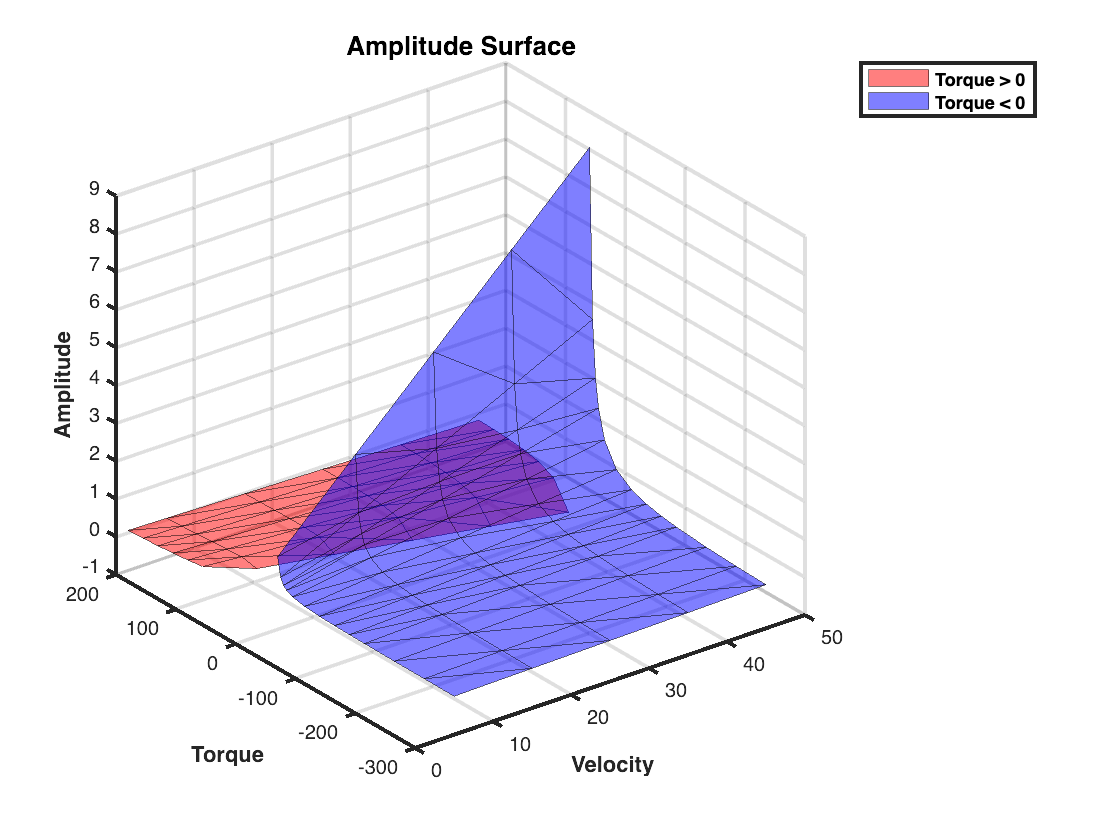

n = length(LMD.Vs);

x = LMD.Vs;
y = LMD.Tm_Tb;
k = LMD.K;

% Separate data for y > 0
idx_positive = y > 0;
x_positive = x(idx_positive);
y_positive = y(idx_positive);
k_positive = k(idx_positive);
t_positive = t(idx_positive);

figure
    % Triangulate and plot for positive y values
    tri_positive = delaunay(x_positive, y_positive);
    %figure;
    a = .5; a2 = .5;
    trisurf(tri_positive, x_positive, y_positive, k_positive, 'FaceColor', 'r', 'FaceAlpha', a, 'EdgeAlpha', a2);
    hold on;

% Separate data for y < 0
idx_negative = y < 0;
x_negative = x(idx_negative);
y_negative = y(idx_negative);
k_negative = k(idx_negative);
t_negative = t(idx_negative);

    % Triangulate and plot for negative y values
    tri_negative = delaunay(x_negative, y_negative);
    trisurf(tri_negative, x_negative, y_negative, k_negative, 'FaceColor', 'b', 'FaceAlpha', a, 'EdgeAlpha', a2);

xlabel('Velocity', 'FontWeight', 'bold');
ylabel('Torque', 'FontWeight', 'bold');
zlabel('Amplitude', 'FontWeight', 'bold');
title('Amplitude Surface', 'FontWeight', 'bold', 'FontSize', 13);
legend('Torque > 0', 'Torque < 0', 'FontWeight', 'bold');
set(gca, 'LineWidth', 2); % You can adjust '2' to change the thickness

axisLimits = axis;

## Rotation Animation 

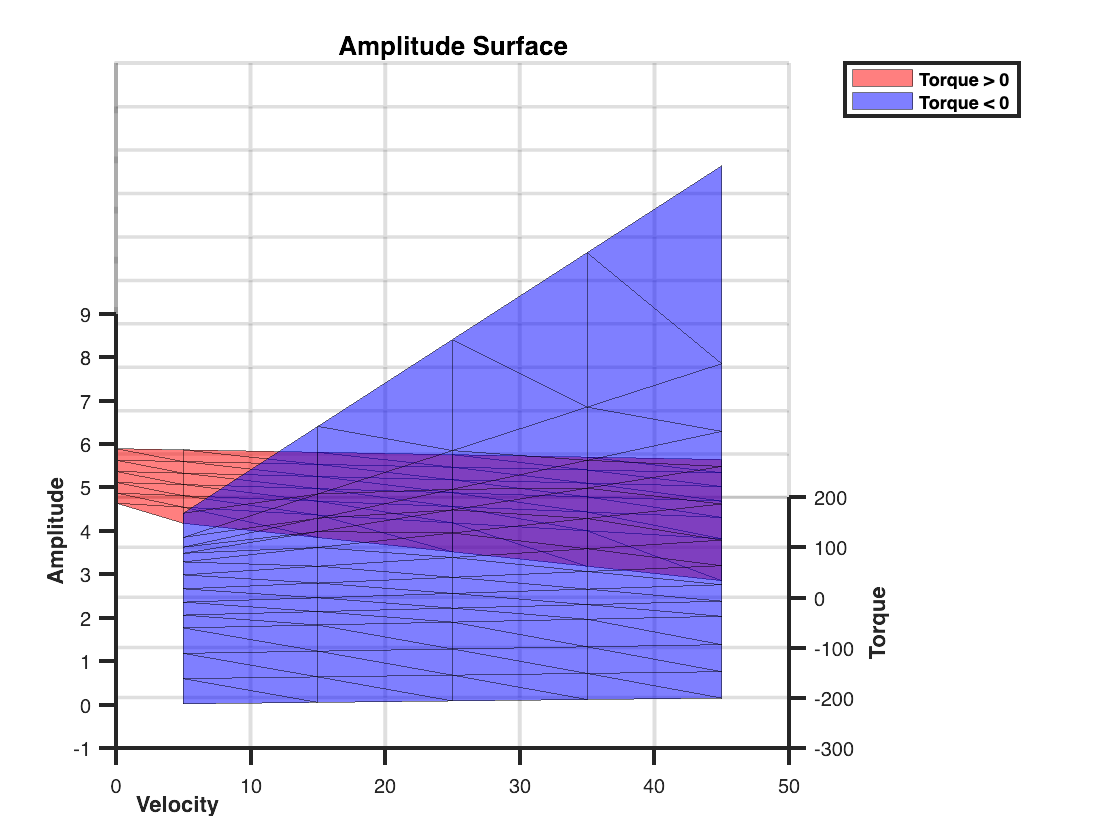

rotAni(axisLimits)

# Time Delay Surface

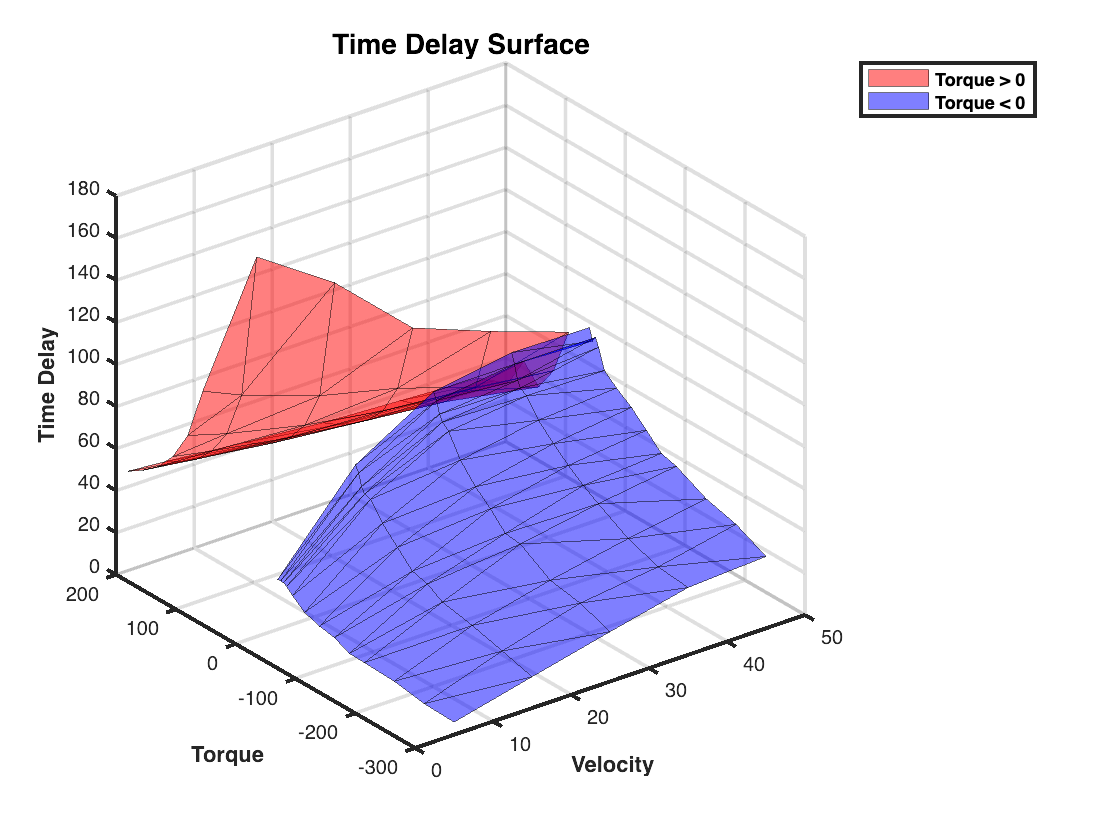

figure
    % Triangulate and plot for positive y values
    tri_positive = delaunay(x_positive, y_positive);
    %figure;
    a = .5; a2 = .5;
    trisurf(tri_positive, x_positive, y_positive, t_positive, 'FaceColor', 'r', 'FaceAlpha', a, 'EdgeAlpha', a2);
    hold on;
    % Triangulate and plot for negative y values
    tri_negative = delaunay(x_negative, y_negative);
    trisurf(tri_negative, x_negative, y_negative, t_negative, 'FaceColor', 'b', 'FaceAlpha', a, 'EdgeAlpha', a2);

xlabel('Velocity', 'FontWeight', 'bold');
ylabel('Torque', 'FontWeight', 'bold');
zlabel('Time Delay', 'FontWeight', 'bold');
title('Time Delay Surface', 'FontWeight', 'bold', 'FontSize', 14);
legend('Torque > 0', 'Torque < 0', 'FontWeight', 'bold');
set(gca, 'LineWidth', 2); % You can adjust '2' to change the thickness

axisLimits = axis;

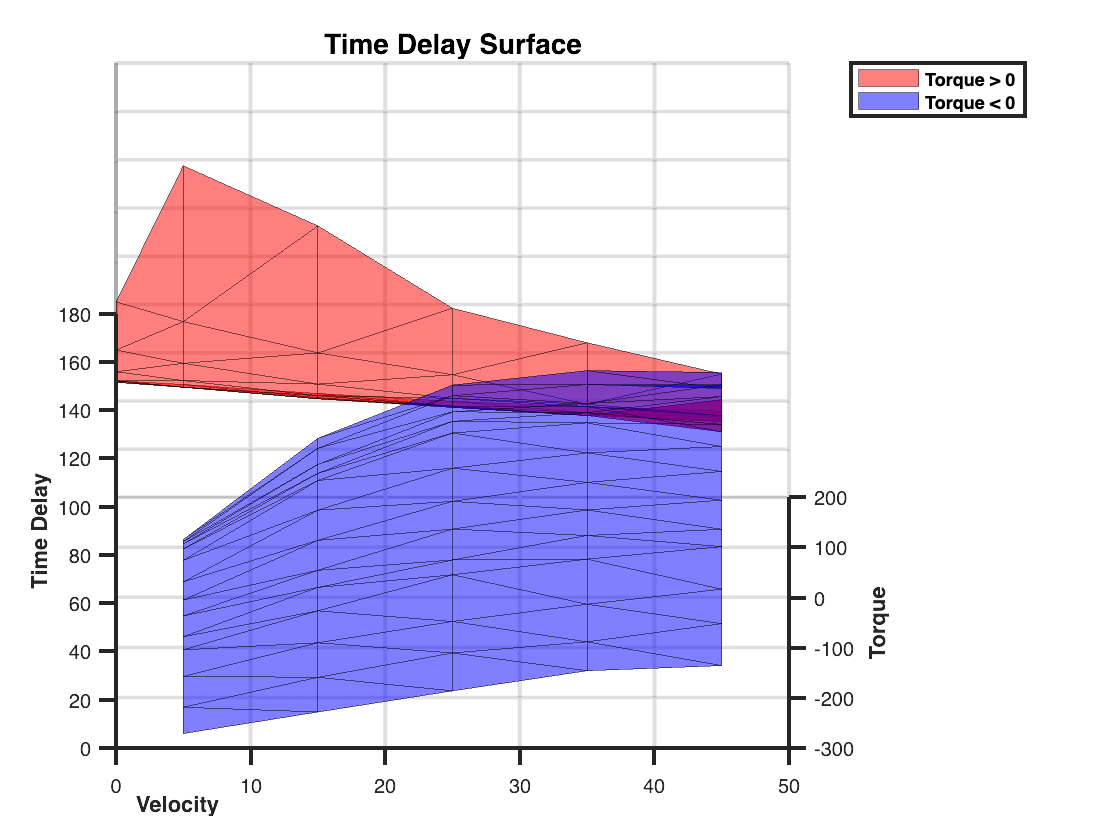

rotAni(axisLimits)

## RMSE

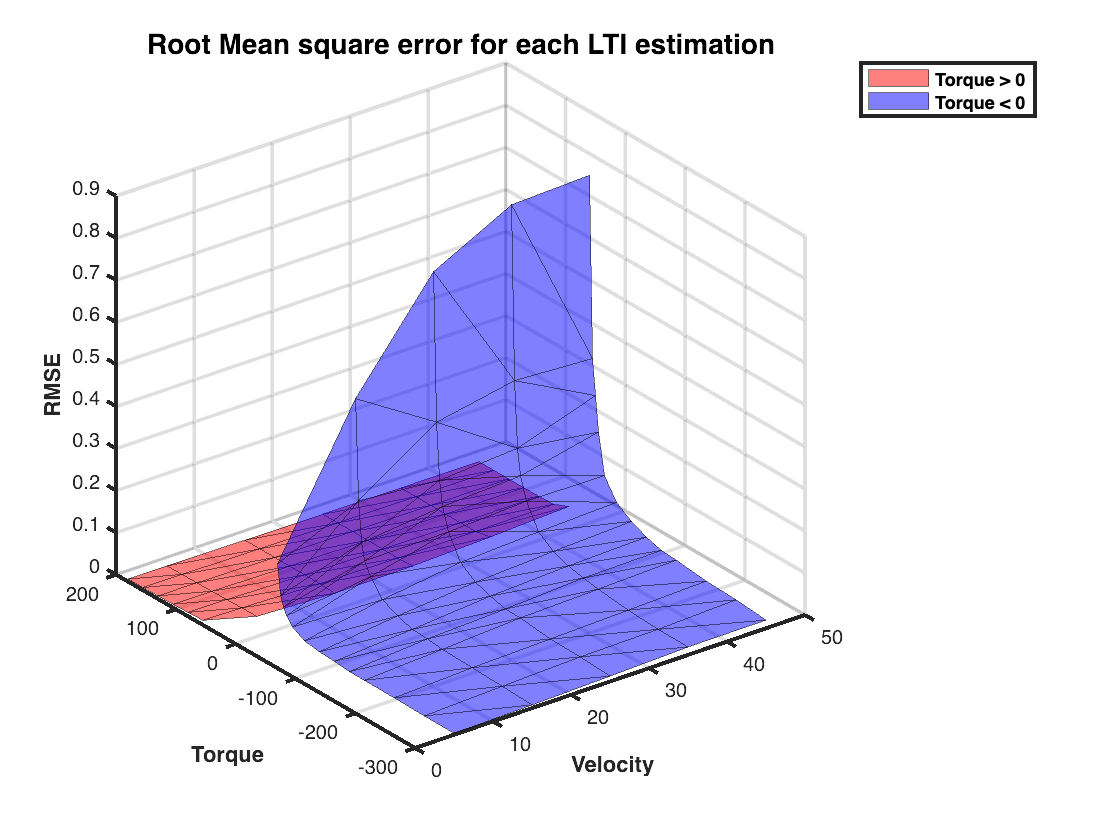

clc; clear; close all;
load('longitudinalModelData80923.mat')
LMD = longitudinalModelData80823;
x = LMD.Vs;
y = LMD.Tm_Tb;
k = LMD.K;
t = LMD.T;
rmse = LMD.rmse;
idx_positive = y > 0;
idx_negative = y < 0;
rmse_positive = rmse(idx_positive);
rmse_negative = rmse(idx_negative);
x_positive = x(idx_positive);
y_positive = y(idx_positive);
x_negative = x(idx_negative);
y_negative = y(idx_negative);

figure
    % Triangulate and plot for positive y values
    tri_positive = delaunay(x_positive, y_positive);
    %figure;
    a = .5; a2 = .5;
    trisurf(tri_positive, x_positive, y_positive, rmse_positive, 'FaceColor', 'r', 'FaceAlpha', a, 'EdgeAlpha', a2);
    hold on;
    % Triangulate and plot for negative y values
    tri_negative = delaunay(x_negative, y_negative);
    trisurf(tri_negative, x_negative, y_negative, rmse_negative, 'FaceColor', 'b', 'FaceAlpha', a, 'EdgeAlpha', a2);

xlabel('Velocity', 'FontWeight', 'bold');
ylabel('Torque', 'FontWeight', 'bold');
zlabel('RMSE', 'FontWeight', 'bold');
title('Root Mean square error for each LTI estimation', 'FontWeight', 'bold', 'FontSize', 14);
legend('Torque > 0', 'Torque < 0', 'FontWeight', 'bold');
set(gca, 'LineWidth', 2); % You can adjust '2' to change the thickness

axisLimits = axis;

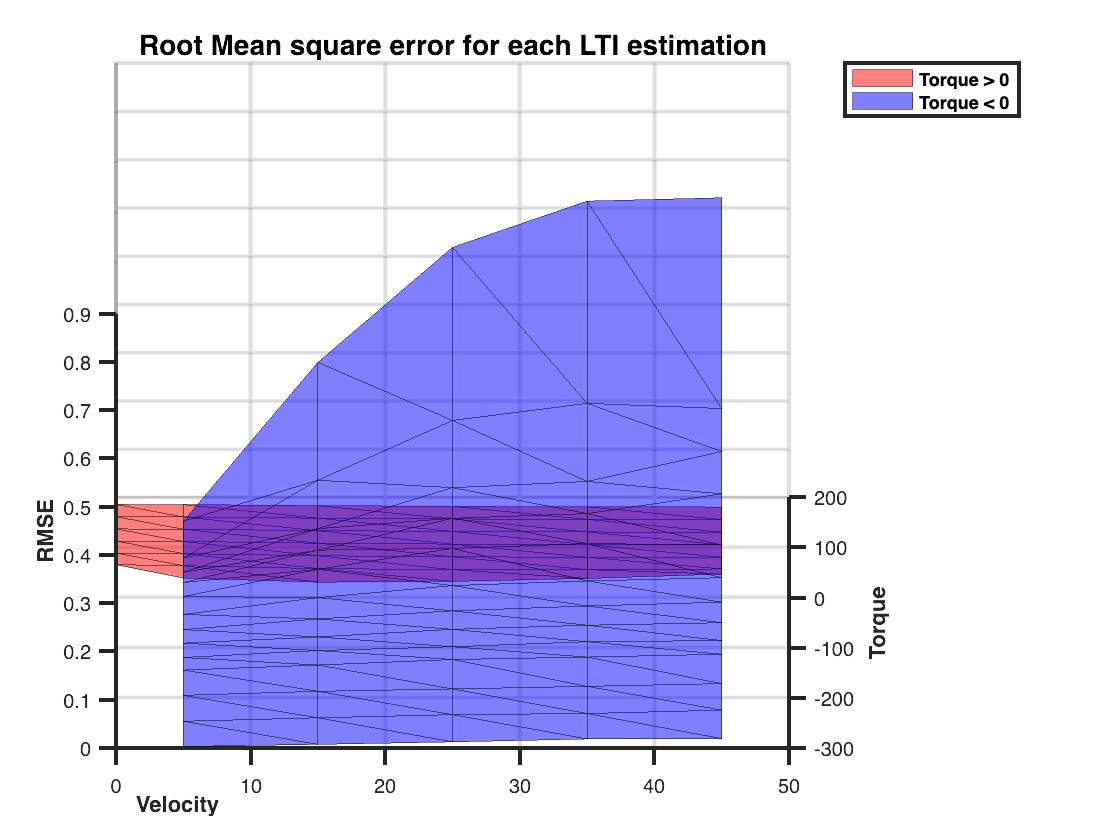

rotAni(axisLimits)

## Rotation Animation Function

function rotAni(axisLimits)
% Define the number of frames and the rotation step
numFrames = 240;
angleStep = 360/numFrames;

filename = 'rotatingAnimation.gif';

% Loop to capture frames and rotate
for frameIdx = 1:numFrames
    % Update the view
    axis(axisLimits);
    azimuth = angleStep * frameIdx;
    view(azimuth, 30);  % Fixed elevation of 30, can be adjusted as needed
    axis(axisLimits);

    % Draw and capture frame
    drawnow;
    currFrame = getframe(gcf);
    im = frame2im(currFrame);
    [A,map] = rgb2ind(im,256);
    
    % Write to the GIF File
    if frameIdx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.05);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.05);
    end
end
end 